# The Deformation Form of Jeffery's Equation

While it is common to predict the orientation of a single fiber by integrating  Jeffery's for $\dot{\mathbf{p}}$, it is also possible to go directly from the initial orientation to the final orientation in one step, using the deformation form of Jeffery's equation.  If a fiber with initial orienation $\mathbf{p}\prime$is subjected to a deformation gradient tensor $\mathbf{F}$ ($F_{ij} = \partial x_i\prime / \partial x_j$), its final orientation is


$$\mathbf{p} = \frac{\mathbf{F} \cdot \mathbf{p}\prime}{| \mathbf{F} \cdot \mathbf{p}\prime |}$$


This relationship is implemented in the function `changep`.  

As an example, for 1-2 simple shearing deformation with shear strain $\gamma$, the deformation gradient is


$$\mathbf{F} = \left[ \begin{array}{ccc}
1 & \gamma t & 0 \\
0 & 1 & 0 \\
0 & 0 & 1
\end{array} \right]$$


Applying this to a single initial orientation (which should be a $3 \times 1$ column vector):

fprintf('For initial orientation\n')

For initial orientation


pprime = [0; 1; 0];  % Edit these values and re-run the section
pprime = pprime/norm(pprime)  % Ensure that pprime has unit length

pprime =      0
     1
     0


fprintf('and shear strain\n')

and shear strain


gamma = 3  % You can also edit this value

gamma = 3

fprintf('the deformation gradient tensor is\n')

the deformation gradient tensor is


F = [1, gamma, 0; 0, 1, 0; 0, 0, 1]

F =      1     3     0
     0     1     0
     0     0     1


fprintf('the final orientation is')

the final orientation is

p = changep(F, pprime)

p =     0.9487
    0.3162
         0


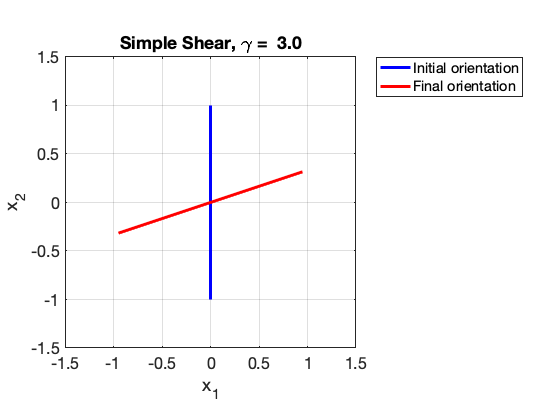


% Drawing this in the 1-2 plane:
plot(pprime(1)*[-1,1], pprime(2)*[-1,1], 'b-', ...
     p(1)*[-1,1], p(2)*[-1,1], 'r-', 'LineWidth', 3)
set(gca, 'FontSize', 16)
legend('Initial orientation', 'Final orientation')
xlabel('x_1'); ylabel('x_2')
axis equal; axis([-1.5 1.5 -1.5 1.5])
grid on
title(sprintf('Simple Shear, \\gamma = %4.1f', gamma))

You can edit the initial orientation `pprime` or the amount of shear strain `gamma` and re-run the script.

As a 3-D example, we can use `randomfibers` to generate a random set of $\mathbf{p}$ vectors on the unit sphere and again transform them according to some $\mathbf{F}$.  We'll also use `p2A` to get the initial and final orientation tensors.  Note that the initial tensor is nearly, but not exactly, isotropic.  This is because the initial orientations are independent random variables.

n = 1000;      % Number of fibers
gamma = 10;    % Amount of shear strain
pprime = randomfibers(n);
fprintf('For %i random fibers the initial orientation is\n', n)

For 1000 random fibers the initial orientation is


Aprime = p2A(pprime)

Aprime =     0.3391    0.0041   -0.0056
    0.0041    0.3302    0.0096
   -0.0056    0.0096    0.3306


F = [1, gamma, 0; 0, 1, 0; 0, 0, 1];
p = changep(F, pprime);
fprintf('After a shear strain of %4.2f, the orientation is\n', gamma)

After a shear strain of 10.00, the orientation is


A = p2A(p)

A =     0.9063    0.0898    0.0024
    0.0898    0.0102    0.0005
    0.0024    0.0005    0.0835


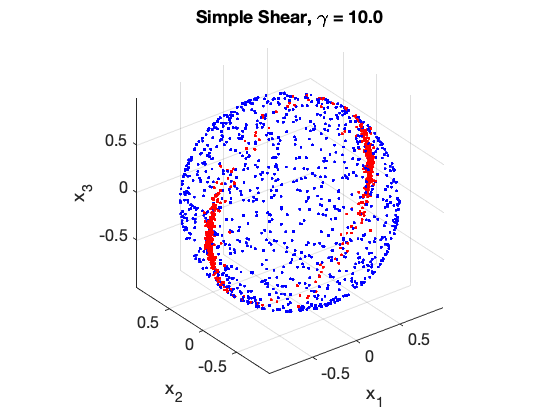


% Plot the fibers as dots on the unit sphere
figure
plot3(pprime(1,:), pprime(2,:), pprime(3,:), 'b.', ...
      p(1,:), p(2,:), p(3,:), 'r.')
axis equal
grid on
set(gca, 'FontSize', 16)
xlabel('x_1'); ylabel('x_2'); zlabel('x_3')
title(sprintf('Simple Shear, \\gamma = %4.1f', gamma))

Click on the figure and use the rotation tool to view the orientations from different directions.